%% OSM STEP 2 - Check GeoJSON building import

clear;
close all;
clc;

%% GeoJSON file

geojsonFile = "osm_buildings_raw.geojson";

if ~isfile(geojsonFile)
    error("GeoJSON file not found. Check that osm_buildings_raw.geojson is in the current MATLAB folder.");
end

%% Read GeoJSON file

buildingsGT = readgeotable(geojsonFile);

fprintf("Number of imported building objects: %d\n", height(buildingsGT));

Number of imported building objects: 5


fprintf("Shape class: %s\n", class(buildingsGT.Shape));

Shape class: geopolyshape



disp("Available table variables:");

Available table variables:


disp(buildingsGT.Properties.VariableNames.');

    {'Shape'           }
    {'full_id'         }
    {'osm_id'          }
    {'osm_type'        }
    {'building'        }
    {'wikipedia'       }
    {'wikidata'        }
    {'postal_code'     }
    {'old_name'        }
    {'name_1'          }
    {'source:geometry' }
    {'source:building' }
    {'operator'        }
    {'type'            }
    {'source:addr'     }
    {'roof:shape'      }
    {'roof:levels'     }
    {'name'            }
    {'building:levels' }
    {'addr:street'     }
    {'addr:housenumber'}
    {'addr:housename'  }
    {'addr:city'       }



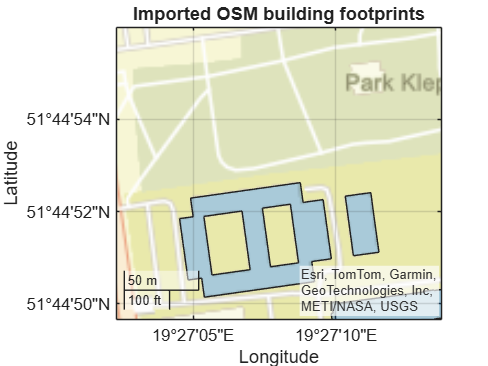


%% Plot buildings in geographic coordinates

figure;
geoplot(buildingsGT.Shape);
geobasemap streets;
title("Imported OSM building footprints");